%perceptron函数
x = [0 0 1 1; 0 1 0 1];
t = [0 1 1 1];
NET = perceptron;%创建二元分类器
net = train(NET,x,t);
view(net)	%view函数就是查看视图
y = net(x);

%创建一个感知器
x = [0 1 0 1; 0 0 1 1];
t = [0 0 0 1];
net = perceptron;
net = configure(net,x,t);
net.iw{1,1}

ans =      0     0


net.b{1}

ans = 0

%训练建立的神经网络
net = train(net,x,t);
net.iw{1,1}

ans =      1     2


net.b{1}

ans = -3

%重新初始化权重和偏差值
net = init(net);
net.iw{1,1}

ans =      0     0


net.b{1}

ans = 0

%netsum函数使用
z1 = [1, 2, 4; 3, 4, 1];
z2 = [-1, 2, 2; -5, -6, 1];
b = [0; -1];
n = netsum({z1, z2, concur(b, 3)})

n =      0     4     6
    -3    -3     1


%dotprod点积
W = rand(4,3);
P = rand(3,1);
Z = dotprod(W,P)

Z =     1.3194
    1.1478
    1.4058
    2.0398


%netprod积函数                          
Z1 = [1 2 4;3 4 1];
Z2 = [-1 2 2; -5 -6 1];
Z = {Z1,Z2};
N = netprod({Z})

N = 1×2 cell 数组
    {2×3 double}    {2×3 double}


B = [0; -1];
Z = {Z1, Z2, concur(B,3)};
N = netprod(Z)

N =      0     0     0
    15    24    -1


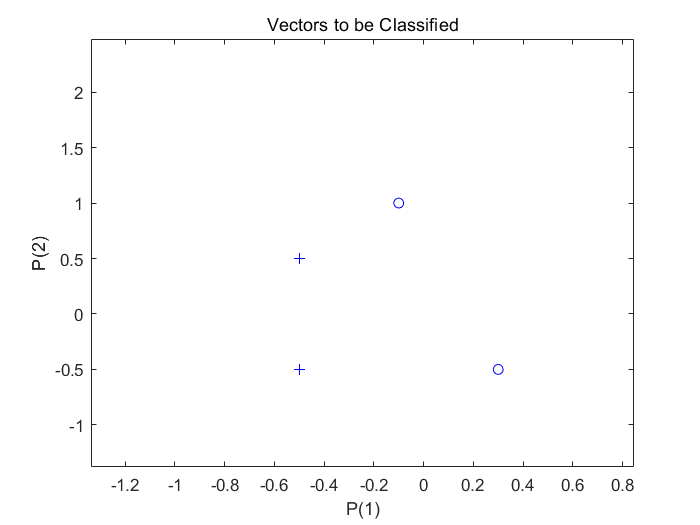

%绘制样本点函数
X = [ -0.5 -0.5 +0.3 -0.1;  
      -0.5 +0.5 -0.5 +1.0];
T = [1 1 0 0];
plotpv(X,T);

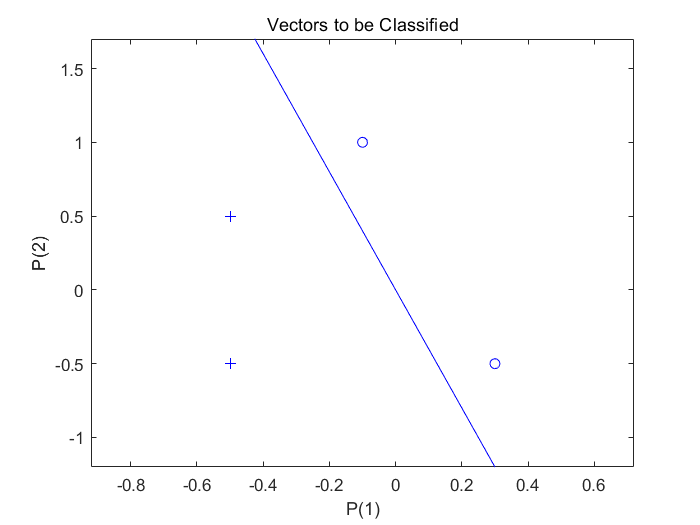

%绘制分类线
net = perceptron;
net = configure(net,X,T);
plotpv(X,T);
plotpc(net.IW{1},net.b{1});
XX = repmat(con2seq(X),1,3);
TT = repmat(con2seq(T),1,3);
net = adapt(net,XX,TT);
plotpc(net.IW{1},net.b{1});

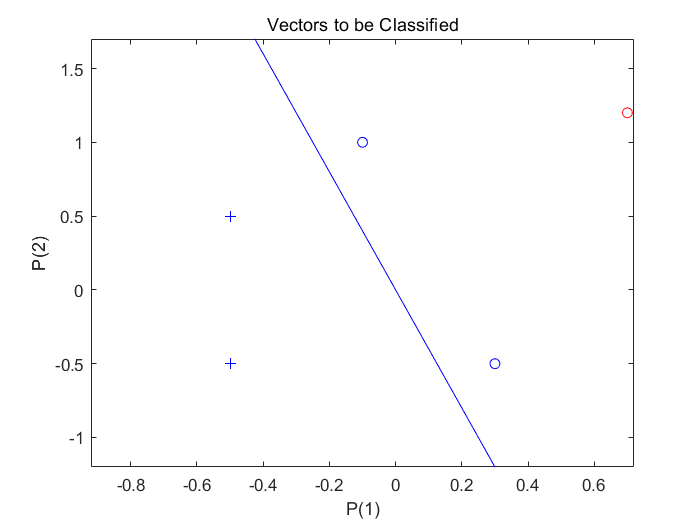

x = [0.7; 1.2];
y = net(x);
plotpv(x,y);
point = findobj(gca,'type','line');
point.Color = 'red';
hold on;
plotpv(X,T);
plotpc(net.IW{1},net.b{1});
hold off;

%感知器学习函数
P = rand(2,1);
T = rand(3,1);
%为空参数不可省略
dw=learnp([],P,[],[],[],[],T,[],[],[],[],[])

dw =     0.3359    0.2921
    0.3489    0.3034
    0.0820    0.0713


%平均绝对值误差函数
net = perceptron;
net = configure(net,0,0);
p = [-10 -5 0 5 10];
t = [0 0 1 1 1];
y = net(p)

y =      1     1     1     1     1


e = t-y

e =     -1    -1     0     0     0


perf = mae(e)

perf = 0.4000